tic
state='growing';
% centres=[0 0; 0.5 0];
% rho_i=[1 0.1];
% a_vec=[-4]';
% b_vec=[13];

centres=[0, 0; 
    0.4551, 0;
    -0.4, 0;
    0.7*cos(1), 0.7*sin(1);
    0.3*cos(-0.8), 0.3*sin(-0.8);
    0.5*cos(-1.3), 0.5*sin(-1.3)];

rho_i=[1,0.05*[1 0.7 1.3 0.6 1.1]];

a_vec=[-4 1 -4 1 1]';
b_vec=[13 10 13 10 10];

flux=0.4;

if flux~=0 && strcmp(state,'growing')~=1
    fprintf('The flux can only be declared nonzero if the axon is growing.\nSetting flux to 0')
    flux=0;
end

max_mesh_spacing=0.02;

model=createpde(1);

N_circles=numel(rho_i);
ns='C'+string((1:N_circles));
ns=char(ns');
ns=ns';
% Create a character array (column vector)

sf=['(C' num2str(1) '-C' num2str(2) ')'];
for i=3:N_circles
sf=['(' sf '-C' num2str(i) ')'];
end
% sf tells matlab what combination of shapes (union, intersection etc) to
% take

C=zeros(4,N_circles); % describe the shapes (same order as in ns)
C(1,:)=ones(1,N_circles);
C(2,:)=centres(:,1)';
C(3,:)=centres(:,2)';
C(4,:)=rho_i;
gm = C;
% A create a matrix whose columns contain the basic shapes making up the domain

g = decsg(gm,sf,ns); %
geometryFromEdges(model,g); % add geometry to model
mesh=generateMesh(model,"Hmax",max_mesh_spacing,'GeometricOrder',"linear");

%pdemesh(mesh)
[p,e,t] = meshToPet(model.Mesh);
N_pts=size(p,2);

[K,~,F1,~,~,~,~]=assempde(model,-1,0,1); % Ks discrete Laplacian on the vertices
%K=K*diag(1./F);

% find what centre boundary points are closest to
boundary_num=(abs(sqrt((p(1,e(1,:))'-centres(:,1)').^2+(p(2,e(1,:))'-centres(:,2)').^2)+...
    -rho_i)<1e-6)*(1:N_circles)';

% sparse(ind_1,ind_2, values, size_1, size_2)
dirichelt_mat=sparse(e(1,:),e(1,:),1,N_pts,N_pts);
E_mat=sparse(e(1,boundary_num~=1),boundary_num(boundary_num~=1)-1,1,...
    N_pts,numel(rho_i)-1); % E

TR=triangulation(t(1:3,:)',p');
tr=t(1:3,cell2mat(edgeAttachments(TR,e(1:2,:)')));
third_ngb=tr(ismember(tr,e(1:2,:))==0)';

drag_matrix_bdry=zeros(size(centres,1)-1,N_pts);

for bdry=2:size(centres,1)
index_array=boundary_num==bdry;
difference_matrix=sparse(e(1,index_array), third_ngb(index_array),...
    1,N_pts,N_pts)+sparse(e(1,index_array),e(1,index_array),-1,...
    N_pts,N_pts);

weight_vector=sparse(1,e(1,index_array),...
    vecnorm(p(:,e(1,index_array))-p(:,e(2,index_array)),2,1)./...
((vecnorm(p(:,third_ngb(index_array))-centres(bdry,:)',2,1)-rho_i(bdry))),...
1,N_pts);
drag_matrix_bdry(bdry-1,:)=weight_vector*difference_matrix;
end

drag_matrix_bdry=sparse(drag_matrix_bdry);
B_mat=sparse(diag(b_vec));
M_1=B_mat\drag_matrix_bdry;
M_2=B_mat\a_vec;

if strcmp(state,'closed')==1 || strcmp(state,'growing')==1
tr=t(1:3,:);
mat1=repmat(1:size(t,2),3,1);
[~,AE] = area(mesh);
area_vec=AE*sparse(mat1(:),tr(:),1,size(t,2),N_pts)/3;

tic
lambda_1=10^4*mean(abs(K),'all');
lambda_2=10^2*mean(abs(K),'all');
% u=(lambda_1*(E_mat*M_1-dirichelt_mat)-K+F1*(F1'*K)/norm(F1)^2+lambda_2*...
%     sparse(1,1,1,N_pts,1)*area_vec)...
%     \(lambda_1*E_mat*M_2);
options = optimoptions('lsqlin','Display','none');
u=lsqlin(lambda_1*(E_mat*M_1-dirichelt_mat)-K+F1*(F1'*K)/norm(F1)^2,...
    lambda_1*E_mat*M_2,[],[],area_vec,flux,[],[],[],options);
omega=M_1*u-M_2
toc
end

% u=cat(1,K,E_mat*M_1-dirichelt_mat)\...
%    cat(1,sparse(N_pts,1),E_mat*M_2); 

if strcmp(state,'open')
lambda=10^4*mean(abs(K),'all');
u=(lambda*(E_mat*M_1-dirichelt_mat)-K)\(lambda*E_mat*M_2);
omega=M_1*u-M_2
end

toc

clf

if numel(rho_i)==2

if strcmp(state,'open')==1
pdeplot(model.Mesh,'XYdata',full(u),'Contour','on','Levels',[0.25 0.2 0.1 0.05 0.02])
end

if strcmp(state,'closed')==1
pdeplot(model.Mesh,'XYdata',full(u),'Contour','on','Levels',[0.2 0.1 0.02 0 -0.02 -0.04 -0.05])
end

if strcmp(state,'growing')==1
pdeplot(model.Mesh,'XYdata',full(u),'Contour','on','Levels',...
    [0.25 0.2 0.15 0.1 0.05])
end

clim([-0.06 0.3])

end

if numel(rho_i)==6

if strcmp(state,'open')==1
 pdeplot(model.Mesh,'XYdata',full(u),'Contour','on',...
'Levels',[0.3 0.2 0.15 0.1 0.05 0 -0.02 -0.05 -0.07 -0.1])
end

if strcmp(state,'closed')==1
pdeplot(model.Mesh,'XYdata',full(u),'Contour','on',...
    'Levels',[0.3 0.2 0.15 0.1 0.05 0 -0.02 -0.05 -0.07 -0.09])
end

if strcmp(state,'growing')==1
pdeplot(model.Mesh,'XYdata',full(u),'Contour','on',...
    'Levels',[0.3 0.27 0.2 0.15 0.1 0.05 0 -0.04])
end

clim([-0.1 0.33])
end

axis equal
set(gca,'visible','off')
set(gca,'Ticklabelinterpreter','latex','FontSize',15)
c=colorbar;
c.Label.String='velocity';

## Asymptotic solution

N_tracks=numel(rho_i)-1;
beta=vecnorm(centres,2,2); beta=beta(2:end);
l_dot=flux/pi;
theta=[0 pi 1 -0.8 -1.3];
%theta=0;

if strcmp(state,'open')==1
 Mat=zeros(N_tracks);
for i=1:N_tracks
    for j=i+1:N_tracks
        Mat(i,j)=0.5*log((beta(i)^2+beta(j)^2-2*beta(i)*beta(j)*cos(theta(i)-theta(j)))/...
        (1+beta(i)^2*beta(j)^2-2*beta(i)*beta(j)*cos(theta(i)-theta(j))));

    end
end

Mat=Mat+triu(Mat,1)';
Mat(1:N_tracks+1:N_tracks^2)=log(rho_i(2:end)'./(1-beta.^2));
p_i=(diag(2*pi./b_vec)-Mat)\(a_vec./b_vec');

G=0;
end



if strcmp(state,'closed')==1
 Mat=zeros(N_tracks);
for i=1:N_tracks
    for j=i+1:N_tracks
        Mat(i,j)=0.5*log((beta(i)^2+beta(j)^2-2*beta(i)*beta(j)*cos(theta(i)-theta(j)))/...
        (1+beta(i)^2*beta(j)^2-2*beta(i)*beta(j)*cos(theta(i)-theta(j))))+(1-beta(i)^2)*(1-beta(j)^2);
    end
end

Mat=Mat+triu(Mat,1)';
Mat(1:N_tracks+1:N_tracks^2)=log(rho_i(2:end)'./(1-beta.^2))+(1-beta.^2).^2;
p_i=(diag(2*pi./b_vec)-Mat)\(a_vec./b_vec');
%p_i=Mat\w_i'; % p_i=-f_i/2*pi

G=4*dot(p_i,beta.^2-1);
end

if strcmp(state,'growing')==1
 Mat=zeros(N_tracks);
for i=1:N_tracks
    for j=i+1:N_tracks
        Mat(i,j)=0.5*log((beta(i)^2+beta(j)^2-2*beta(i)*beta(j)*cos(theta(i)-theta(j)))/...
        (1+beta(i)^2*beta(j)^2-2*beta(i)*beta(j)*cos(theta(i)-theta(j))))+(1-beta(i)^2)*(1-beta(j)^2);
    end
end

Mat=Mat+triu(Mat,1)';
Mat(1:N_tracks+1:N_tracks^2)=log(rho_i(2:end)'./(1-beta.^2))+(1-beta.^2).^2;
%p_i=Mat\(w_i'-2*l_dot*(1-beta.^2)'); % p_i=-f_i/2*pi

p_i=(diag(2*pi./b_vec)-Mat)\(a_vec./b_vec'+2*l_dot*(1-beta.^2));

G=4*dot(p_i,beta.^2-1)-8*l_dot;
end

R=vecnorm(mesh.Nodes);
asymptotic_solution=0;


for i=1:N_tracks
    e_i=centres(i+1,:)/beta(i);
    asymptotic_solution=asymptotic_solution+p_i(i)*log(vecnorm(mesh.Nodes-beta(i)*e_i')./vecnorm(beta(i)*mesh.Nodes-e_i'));
end
asymptotic_solution=asymptotic_solution+G*(R.^2-1)/4;

Mat*p_i;

clf

if numel(rho_i)==2

if strcmp(state,'open')==1
pdeplot(model.Mesh,'XYdata',asymptotic_solution,'Contour','on','Levels',[0.25 0.2 0.1 0.05 0.02])
end

if strcmp(state,'closed')==1
pdeplot(model.Mesh,'XYdata',asymptotic_solution,'Contour','on','Levels',[0.2 0.1 0.02 0 -0.02 -0.04 -0.05])
end

if strcmp(state,'growing')==1
pdeplot(model.Mesh,'XYdata',asymptotic_solution,'Contour','on','Levels',...
    [0.25 0.2 0.15 0.1 0.05])
end

clim([-0.06 0.3])

end

if numel(rho_i)==6

if strcmp(state,'open')==1
 pdeplot(model.Mesh,'XYdata',asymptotic_solution,'Contour','on',...
'Levels',[0.3 0.2 0.15 0.1 0.05 0 -0.02 -0.05 -0.07 -0.1])
end

if strcmp(state,'closed')==1
pdeplot(model.Mesh,'XYdata',asymptotic_solution,'Contour','on',...
    'Levels',[0.3 0.2 0.15 0.1 0.05 0 -0.02 -0.05 -0.07 -0.09])
end

if strcmp(state,'growing')==1
pdeplot(model.Mesh,'XYdata',asymptotic_solution,'Contour','on',...
    'Levels',[0.3 0.27 0.2 0.15 0.1 0.05 0 -0.04])
end

clim([-0.1 0.33])
end

axis equal
axis off
set(gca,'Ticklabelinterpreter','latex','FontSize',12)
c=colorbar;
c.Label.String='velocity';
c.Ruler.TickLabelRotation=90;

model.Mesh

rho=0.5;
a_1=-2;
b_1=3;
[1-rho^2 log(rho) -1; 
 (1-rho^2)^2/4 rho^2*(1-2*log(rho))/4-1/4 0;
 -4*pi*rho^2 2*pi -b_1]\[0; 0; a_1]

rho_i=[1 0.5];
centres=[0 0; 0 0];
a_vec=[-2];
b_vec=[3];
tic
Lagrangian(centres,rho_i,a_vec,b_vec,'closed')
toc
% G, A, omega

#### One Track

rho_i=[1 0.15];
a_vec=2*[-1];
b_vec=[1];
range=linspace(0,1-rho_i(2)-0.05,20);
score_vec=0*range;

for i=1:numel(score_vec)
    centres=[0 0; range(i) 0];
    score_vec(i)=Lagrangian(centres,rho_i,a_vec,b_vec,'closed');
end

clf
plot(range,score_vec,'LineWidth',2,'Color','blue')
hold on
[pks,locs]=findpeaks(score_vec);
xline(range(locs(2)),'--','linewidth',2)
text(0.52,0.25,num2str(range(locs(2))),'FontSize',20)
hold off
xlabel('$$x_0$$','Interpreter','latex','FontSize',15)
ylabel('$$\mathcal L$$','Interpreter','latex','FontSize',15)
set(gca,'fontsize',15)
grid on

#### Two Tracks

rho_i=[1 0.15 0.15];
a_vec=2*[-1; 1];
b_vec=[1 1];
range=linspace(rho_i(2)+0.05,1-rho_i(2)-0.05,20);
score_vec=0*range;

for i=1:numel(score_vec)
    centres=[0 0; range(i) 0; -range(i) 0];
    score_vec(i)=Lagrangian(centres,rho_i,a_vec,b_vec,'closed');
end

clf
plot(range,score_vec,'LineWidth',2,'Color','blue')
hold on
[pks,locs]=findpeaks(score_vec);
xline(range(locs),'--','linewidth',2)
text(0.5,0.5,num2str(range(locs)),'FontSize',20)
hold off
xlabel('$$x_0$$','Interpreter','latex','FontSize',15)
ylabel('$$\mathcal L$$','Interpreter','latex','FontSize',15)
set(gca,'fontsize',15)
grid on

# Hill Optimisation for N tracks

rho_i=[1 0.15*ones(1,6)];
a_vec=[-4*ones(1,2) 1*ones(1,4)]';
b_vec=[13*ones(1,2) 10*ones(1,4)]';

% a_vec=[-ones(1,4) ones(1,2)]';
% b_vec=[ones(1,4) ones(1,2)]';
flux=0; % this is an imposed axial flux.
% The fully closed case has state=closed and flux=0;
% The growing case has state=close and flux neq 0
cut_off=0.05;
N_iterations=10;
N_max_attempts=100;

state='open';

centres=[0 0; random_discs_fun(rho_i(2:end), cut_off)];
Score=Lagrangian(centres,rho_i,a_vec,b_vec,state,flux);
Score_new=-Inf;



for N_iter=1:N_iterations
    N_iter
for i=1:(numel(rho_i)-1)

for N_attempts=1:N_max_attempts
centres_trial=[0 0; new_random_disc(rho_i(2:end)',centres(2:end,:),i, cut_off)];
Score_new=Lagrangian(centres_trial,rho_i,a_vec,b_vec,state,flux);

if Score_new>Score
centres=centres_trial;
Score=Score_new;
break
end

end

end
end

N_iter = 1

N_iter = 2

N_iter = 3

N_iter = 4

N_iter = 5

N_iter = 6

N_iter = 7

N_iter = 8

N_iter = 9

N_iter = 10

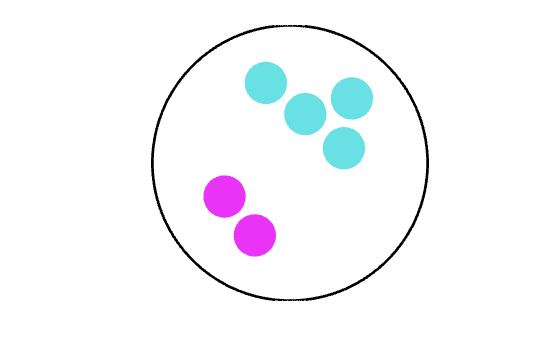

clf
colors=[0.914 0.2 0.969;0.9*[0.455 0.976 0.992]]; %dynein in cyan
hold on
viscircles(centres(1,:),1,'Color',[0 0 0]);
for i=2:size(centres,1)
%viscircles(centres(i,:),rho_i(i),'Color',colors((a_vec(i-1)>0)+1,:));

rectangle('Position',[centres(i,1)-rho_i(i),centres(i,2)-rho_i(i),2*rho_i(i),2*rho_i(i)],...
        'Curvature',[1 1],'EdgeColor',colors((a_vec(i-1)>0)+1,:),'FaceColor',colors((a_vec(i-1)>0)+1,:))
end
hold off
axis equal
set(gca,'visible','off')

max_mesh_spacing=0.02;

model=createpde(1);

N_circles=numel(rho_i);
ns='C'+string((1:N_circles));
ns=char(ns');
ns=ns';
% Create a character array (column vector)

sf=['(C' num2str(1) '-C' num2str(2) ')'];
for i=3:N_circles
sf=['(' sf '-C' num2str(i) ')'];
end
% sf tells matlab what combination of shapes (union, intersection etc) to
% take

C=zeros(4,N_circles); % describe the shapes (same order as in ns)
C(1,:)=ones(1,N_circles);
C(2,:)=centres(:,1)';
C(3,:)=centres(:,2)';
C(4,:)=rho_i;
gm = C;
% A create a matrix whose columns contain the basic shapes making up the domain

g = decsg(gm,sf,ns); %
geometryFromEdges(model,g); % add geometry to model
mesh=generateMesh(model,"Hmax",max_mesh_spacing,'GeometricOrder',"linear");

%pdemesh(mesh)
[p,e,t] = meshToPet(model.Mesh);
N_pts=size(p,2);

[K,~,F1,~,~,~,~]=assempde(model,-1,0,1); % Ks discrete Laplacian on the vertices
%K=K*diag(1./F);

% find what centre boundary points are closest to
boundary_num=(abs(sqrt((p(1,e(1,:))'-centres(:,1)').^2+(p(2,e(1,:))'-centres(:,2)').^2)+...
    -rho_i)<1e-6)*(1:N_circles)';

% sparse(ind_1,ind_2, values, size_1, size_2)
dirichelt_mat=sparse(e(1,:),e(1,:),1,N_pts,N_pts);
E_mat=sparse(e(1,boundary_num~=1),boundary_num(boundary_num~=1)-1,1,...
    N_pts,numel(rho_i)-1); % E

TR=triangulation(t(1:3,:)',p');
tr=t(1:3,cell2mat(edgeAttachments(TR,e(1:2,:)')));
third_ngb=tr(ismember(tr,e(1:2,:))==0)';

drag_matrix_bdry=zeros(size(centres,1)-1,N_pts);

for bdry=2:size(centres,1)
index_array=boundary_num==bdry;
difference_matrix=sparse(e(1,index_array), third_ngb(index_array),...
    1,N_pts,N_pts)+sparse(e(1,index_array),e(1,index_array),-1,...
    N_pts,N_pts);

weight_vector=sparse(1,e(1,index_array),...
    vecnorm(p(:,e(1,index_array))-p(:,e(2,index_array)),2,1)./...
((vecnorm(p(:,third_ngb(index_array))-centres(bdry,:)',2,1)-rho_i(bdry))),...
1,N_pts);
drag_matrix_bdry(bdry-1,:)=weight_vector*difference_matrix;
end

drag_matrix_bdry=sparse(drag_matrix_bdry);
B_mat=sparse(diag(b_vec));
M_1=B_mat\drag_matrix_bdry;
M_2=B_mat\a_vec;

if strcmp(state,'closed')==1 || strcmp(state,'growing')==1
tr=t(1:3,:);
mat1=repmat(1:size(t,2),3,1);
[~,AE] = area(mesh);
area_vec=AE*sparse(mat1(:),tr(:),1,size(t,2),N_pts)/3;

tic
lambda_1=10^4*mean(abs(K),'all');
lambda_2=10^2*mean(abs(K),'all');
% u=(lambda_1*(E_mat*M_1-dirichelt_mat)-K+F1*(F1'*K)/norm(F1)^2+lambda_2*...
%     sparse(1,1,1,N_pts,1)*area_vec)...
%     \(lambda_1*E_mat*M_2);
options = optimoptions('lsqlin','Display','none');
u=lsqlin(lambda_1*(E_mat*M_1-dirichelt_mat)-K+F1*(F1'*K)/norm(F1)^2,...
    lambda_1*E_mat*M_2,[],[],area_vec,flux,[],[],[],options);
omega=M_1*u-M_2;
toc
end

Elapsed time is 4.937125 seconds.



% u=cat(1,K,E_mat*M_1-dirichelt_mat)\...
%    cat(1,sparse(N_pts,1),E_mat*M_2); 

if strcmp(state,'open')
lambda=10^4*mean(abs(K),'all');
u=(lambda*(E_mat*M_1-dirichelt_mat)-K)\(lambda*E_mat*M_2);
omega=M_1*u-M_2;
end

mean(omega(1:2))

ans = 0.3131

mean(omega(3:6))

ans = -0.0367

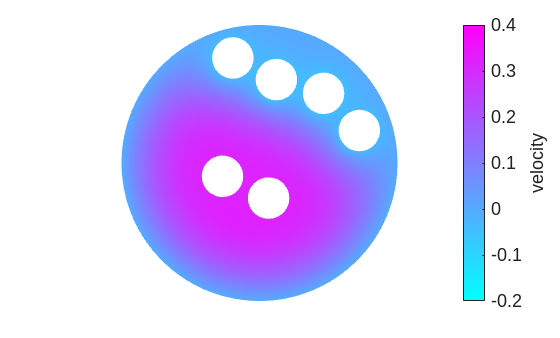

% sum_kinesin=sum_kinesin+sum(omega(1:2));
% sum_dynein=sum_dynein+sum(omega(3:6));
% counter=counter+1
% % 
% sum_kinesin/(2*counter)
% sum_dynein/(4*counter)
pdeplot(model.Mesh,'XYdata',full(u))


clim([-0.2 0.4])


axis equal
set(gca,'visible','off')
set(gca,'Ticklabelinterpreter','latex','FontSize',15)
c=colorbar;
c.Label.String='velocity';

[~,transport_velocities,drags]=Lagrangian(centres,rho_i,a_vec,b_vec,state,flux)
a_vec+transport_velocities.*b_vec

# Monte Carlo Optimisation for N tracks

rho_i=[1 0.15*ones(1,8)];
a_vec=[-2*ones(1,4) 2*ones(1,4)]';
b_vec=1*ones(1,8);
cut_off=0.05;
N_iterations=10000;

Lagrangian_highest=-Inf;

for i=1:N_iterations
centres=[0 0; random_discs_fun(rho_i(2:end), cut_off)];
Score=Lagrangian(centres,rho_i,a_vec,b_vec,'closed');

if Score>Lagrangian_highest
best=centres;
Lagrangian_highest=Score;
end
end


%filename=['Numerical_4_2_Tracks_Closed.mat'];
%save(filename,'a_vec','b_vec','centres','cut_off','rho_i');

clf
colors=[1 0 0; 0 0 1];
hold on
viscircles(best(1,:),1,'Color','black');
for i=2:size(best,1)
viscircles(best(i,:),rho_i(i),'Color',colors((a_vec(i-1)>0)+1,:));
end
hold of
axis equal

applyBoundaryCondition(model,"dirichlet", "Edge",1:model.Geometry.NumEdges,"u",0);
[Ks,Fs] = assempde(model,-1,0,1);
u=Ks\Fs;

num=210;
U(num)
u(num)

[Kc,Fc,B,ud]=assempde(model,-1,0,1);
%Ks is the finite difference matrix acting on the nodes,
% purely a function of geometry
[K,M,F_1,Q,G_mat,H,R]=assempde(model,-1,0,1);
% K finite difference matrix acting on the nodes,
% purely a function of geometry
% M mass matrix (zero if a=0)
% F load vector
% Q Neumann boundary conditions matrix (zero)
% G_mat: Neumann bcs vector (here zero)
% H Dirichelt matrix
% R Dirichelt vector

% Want u to integrate to 0. Define a vector of node weigths (each weight is
% 1/3 of the sum of triangle areas joined at that vertex).
N_vert=size(mesh.Nodes,2);
N_boundary_vert=size(H,1);
% the first N_boundary_vert vertices are on the boundary, where the velocity is given

% Want dot(N,U)=0;

% Want to solve K*U=F subject to H*U=R. Can do this by concatenating arrays
L=10^2;
Proj_F1=eye(N_vert)-F_1*F_1'/norm(F_1)^2;
Proj_N=eye(N_vert)-N*N'/norm(N)^2;
U=cat(1,L*H'*H-Proj_F1*K,N')\cat(1,L*H'*R,0);
[~,integral]=integrate_fun_trimesh(mesh.Nodes,mesh.Elements,U')
mean(K*U./F_1)
%pdeplot(model,"XYData",results.NodalSolution)
pdeplot(model,"XYData",U)
axis equal
axis off
set(gca,'Ticklabelinterpreter','latex','FontSize',20)
c=colorbar;
c.Label.String='velocity'

% Compute the O(1) asymptotic solution for small lambda
% Mat=[log(lambda*n_1/(1-beta_1^2)), log(norm(beta_1*e_1-beta_2*e_2)/norm(beta_1*beta_2*e_1-e_2));
%    log(norm(beta_1*e_1-beta_2*e_2)/norm(beta_1*beta_2*e_2-e_1)), log(lambda*n_2/(1-beta_2^2))];
% 
% vec=Mat\[w1+G*(1-beta_1^2)/4;w2+G*(1-beta_2^2)/4];
% a1=vec(1);
% a2=vec(2);
% 
% R=vecnorm(mesh.Nodes);
% 
% asymptotic_solution=a1*log(vecnorm(mesh.Nodes-beta_1*e_1')./vecnorm(beta_1*mesh.Nodes-e_1'))+...
% a2*log(vecnorm(mesh.Nodes-beta_2*e_2')./vecnorm(beta_2*mesh.Nodes-e_2'))+...
% G*(R.^2-1)/4;

R=vecnorm(mesh.Nodes);
asymptotic_solution=0;
for i=1:N_circles
    e_i=[cos(theta(i)),sin(theta(i))];
    asymptotic_solution=asymptotic_solution+p_i(i)*log(vecnorm(mesh.Nodes-beta(i)*e_i')./vecnorm(beta(i)*mesh.Nodes-e_i'));
end
asymptotic_solution=asymptotic_solution+G*(R.^2-1)/4;

fig=pdeplot(mesh,"XYData",asymptotic_solution);
[~,integral]=integrate_fun_trimesh(mesh.Nodes,mesh.Elements,results.NodalSolution');
fprintf("The flux is %f",integral)
[~,integral]=integrate_fun_trimesh(mesh.Nodes,mesh.Elements,asymptotic_solution);
axis equal
axis off
set(gca,'Ticklabelinterpreter','latex','FontSize',20)
c=colorbar;
%colorbar('Fontsize',40)
c.Label.String='velocity';
pdeplot(mesh,"XYData",abs(asymptotic_solution'-results.NodalSolution));
axis equal
axis off
set(gca,'Ticklabelinterpreter','latex','FontSize',20)
c=colorbar;
%colorbar('Fontsize',40)
c.Label.String='error';

radii=0.1*ones(1,10)';
centres=random_discs_fun(radii, 0.1);
clf
viscircles(centres,radii);
hold on
viscircles([0 0],1);
axis equal
hold off



function [Score,transport_velocities,drags]=Lagrangian(centres,rho_i,a_vec,b_vec,state,flux)
max_mesh_spacing=0.03;

model=createpde(1);

N_circles=numel(rho_i);
ns='C'+string((1:N_circles));
ns=char(ns');
ns=ns';
% Create a character array (column vector)

sf=['(C' num2str(1) '-C' num2str(2) ')'];
for i=3:N_circles
sf=['(' sf '-C' num2str(i) ')'];
end
% sf tells matlab what combination of shapes (union, intersection etc) to
% take

C=zeros(4,N_circles); % describe the shapes (same order as in ns)
C(1,:)=ones(1,N_circles);
C(2,:)=centres(:,1)';
C(3,:)=centres(:,2)';
C(4,:)=rho_i;
gm = C;
% A create a matrix whose columns contain the basic shapes making up the domain

g = decsg(gm,sf,ns); %
geometryFromEdges(model,g); % add geometry to model
mesh=generateMesh(model,"Hmax",max_mesh_spacing,'GeometricOrder',"linear");

%pdemesh(mesh)
[p,e,t] = meshToPet(model.Mesh);
N_pts=size(p,2);

[K,~,F1,~,~,~,~]=assempde(model,-1,0,1); % Ks discrete Laplacian on the vertices
%K=K*diag(1./F);

% find what centre boundary points are closest to
boundary_num=(abs(sqrt((p(1,e(1,:))'-centres(:,1)').^2+(p(2,e(1,:))'-centres(:,2)').^2)+...
    -rho_i)<1e-6)*(1:N_circles)';

% sparse(ind_1,ind_2, values, size_1, size_2)
dirichelt_mat=sparse(e(1,:),e(1,:),1,N_pts,N_pts);
E_mat=sparse(e(1,boundary_num~=1),boundary_num(boundary_num~=1)-1,1,...
    N_pts,numel(rho_i)-1); % E

TR=triangulation(t(1:3,:)',p');
tr=t(1:3,cell2mat(edgeAttachments(TR,e(1:2,:)')));
third_ngb=tr(ismember(tr,e(1:2,:))==0)';

drag_matrix_bdry=zeros(size(centres,1)-1,N_pts);

for bdry=2:size(centres,1)
index_array=boundary_num==bdry;
difference_matrix=sparse(e(1,index_array), third_ngb(index_array),...
    1,N_pts,N_pts)+sparse(e(1,index_array),e(1,index_array),-1,...
    N_pts,N_pts);

weight_vector=sparse(1,e(1,index_array),...
    vecnorm(p(:,e(1,index_array))-p(:,e(2,index_array)),2,1)./...
((vecnorm(p(:,third_ngb(index_array))-centres(bdry,:)',2,1)-rho_i(bdry))),...
1,N_pts);
drag_matrix_bdry(bdry-1,:)=weight_vector*difference_matrix;
end

drag_matrix_bdry=sparse(drag_matrix_bdry);
B_mat=sparse(diag(b_vec));
M_1=B_mat\drag_matrix_bdry;
M_2=B_mat\a_vec;

if strcmp(state,'closed')
tr=t(1:3,:);
mat1=repmat(1:size(t,2),3,1);
[~,AE] = area(mesh);
area_vec=AE*sparse(mat1(:),tr(:),1,size(t,2),N_pts)/3;

lambda_1=10^4*mean(abs(K),'all');
options = optimoptions('lsqlin','Display','none');
u=lsqlin(lambda_1*(E_mat*M_1-dirichelt_mat)-K+F1*(F1'*K)/norm(F1)^2,...
    lambda_1*E_mat*M_2,[],[],area_vec,flux,[],[],[],options);
end

if strcmp(state,'open')
lambda=10^4*mean(abs(K),'all');
u=(lambda*(E_mat*M_1-dirichelt_mat)-K)\(lambda*E_mat*M_2);
end

transport_velocities=M_1*u-M_2;
Score=-dot(sign(a_vec),transport_velocities);
drags=drag_matrix_bdry*u;
end








function [area,integral] = integrate_fun_trimesh(p,t,f)
%--------------------------------------------------------------------
%
% Integrate a function f evaluated at the nodes p of 2D linear
% triangulation t, using linear interpolation of the function. 
%
% The triangulation can be arbitrary, comprising disconnected or 
% multiply-connnected domains.
%
% Inputs:  p is a 2xN matrix of [x;y] nodal coordinates.
%          t is a 3xE node connectivity matrix for the nodes in p.
%          f is a N-vector of values of the function you wish to 
%            integrate over the triangulation, given at the nodes p.
%
% Outputs: area is the area of the triangulation.
%          integral is the integral of f over the triangulation.
%
% Author: Tom Montenegro-Johnson
% http://www.damtp.cam.ac.uk/user/tdj23
% Release date: Nov 2015
%
%--------------------------------------------------------------------
%Corner point indices
it1 = t(1,:);
it2 = t(2,:);
it3 = t(3,:);
%Affine transform to canonical element
detadx = p(2,it1) - p(2,it2);
detady = p(1,it2) - p(1,it1);
dpsidx = p(2,it3) - p(2,it1);
dpsidy = p(1,it1) - p(1,it3);
%Jacobian of transform
jac = dpsidx.*detady-dpsidy.*detadx;
jac = 0.5*jac;
%Gauss points on canonical triangle
[psi,eta,w] = gausspoints;
weights = w(:)*ones(1,length(jac));
%Shape functions on linear triangle
[phi,~,~] = shapes(psi,eta);
%Corner points of function
f1 = f(it1);
f2 = f(it2);
f3 = f(it3);
f_out = phi(1,:)'*f1 + phi(2,:)'*f2 + phi(3,:)'*f3;
%Do the integration
area = sum(jac);
elm_integrals = sum(f_out.*weights,1).*jac;
integral = sum(elm_integrals);
end
function [psi,eta,w] = gausspoints
    %Degree of precision 2, sufficient for linear interpolation
    psi=[2/3 1/6 1/6];
	eta=[1/6 1/6 2/3];
	w=[1/3 1/3 1/3];
end
function [phi,dphidx,dphidy] = shapes(x,y)
    %Linear shape functions on canonical triangle
    phi    = [1-x-y  ; x     ; y];
    dphidx = [-1+0*x ; 1+0*x ; 0*x];
    dphidy = [-1+0*x ; 0*x   ; 1+0*x];
end

function y=random_discs_fun(radii, cut_off)
centres=ones(numel(radii),2);
N_max_attempts=10^4;

for i=1:numel(radii)
N_attempts=0;

while N_attempts<N_max_attempts
r=sqrt(rand)*(1-radii(i)-cut_off); theta=2*pi*rand;
centres(i,:)=r*[cos(theta), sin(theta)];

if all(vecnorm(centres(i,:)-centres(1:i-1,:),2,2)>radii(1:i-1)+radii(i)+cut_off)
        break
end
N_attempts=N_attempts+1;

end
end
y=centres;
end


function y=new_random_disc(radii,positions,i, cut_off)
N_max_attempts=10^4;
N_attempts=1;

while N_attempts<N_max_attempts
r=sqrt(rand)*(1-radii(i)-cut_off); theta=2*pi*rand;
positions(i,:)=r*[cos(theta), sin(theta)];

if all(vecnorm(positions(i,:)-positions([1:i-1,(i+1):end],:),2,2)>...
        radii([1:i-1,(i+1):end])+radii(i)+cut_off)
        break
end
N_attempts=N_attempts+1;
end
y=positions;
end